# SIRD-DDFT calibration using OC

Here we will perform further tests on the ODE solver. First we define the spectral box for spatial discretisation and a spectral line for time evaluation.

% Number of colloqation points per dimension
N1 = 30;    % base is 30
N2 = 30;
N  = N1 * N2;                 dims = {N1, N2, N};
% Define the geometry of the box
geom.y1Min = -5;        geom.y1Max =  5;
geom.y2Min = -5;        geom.y2Max =  5;
geom.N = [N1;N2];
% Set up a box object using the pre-defined class
box  = BoxFourierFourier(geom);
Diff = box.ComputeDifferentiationMatrix;
grad = Diff.grad;

Interp = box.ComputeInterpolationMatrix(...
                                    (0:0.02:1)',(0:0.02:1)',true,true);
% Create the points, differentiation matrices, integration vector, and indices
%[Pts,Diff,Int,Ind] = box.ComputeAll();
Pts = box.Pts;

% Time collocation points
tMax = 50.0; % Usually T = 50
n_t  = 70;   % often 100
% Set up a time line where we are currently at 
ge.yMin  = 0;    ge.yMax = tMax;    ge.N = n_t;
aLine    = SpectralLine(ge);
outTimes = aLine.Pts.y;
%Interp_Time = aLine.ComputeInterpolationMatrix((-1:0.01:1)',true);

% Integration weights
Int_Spatial = box.ComputeIntegrationVector;
Int_Time    = aLine.ComputeIntegrationVector;
Interp_Time = aLine.ComputeInterpolationMatrix((-1:0.02:1)',true);

Now let us define the initial condition:

[rho_ic,N_T] = InitialCondition(Pts.y1_kv,Pts.y2_kv,Int_Spatial,N);

Also create a Kernel:

data.s_sd = 3.0;
data.s_si = 3.0;
Conv = box.ComputeConvolutionMatrix(@(y1,y2) Kernels(y1,y2,data),true);

% Regularisation parameter
tik = 1e-4;

% Precompute \nabla K_u (*) and \nabla K_v (*)
gConv_u = grad * Conv(:,:,1);       %786 * 0.046002
gConv_v = grad * Conv(:,:,2);       %786 * 0.046002

Parameters for advection:

G_S = 1.0;    % Mobility of Susceptibles [p8]
G_I = 1.0;    % Mobility of Infected [p8]
G_R = 1.0;    % Mobility of Recovered [p8]
G = {G_S, G_I, G_R};

D = 0.01;      % General diffusion 

%u = ((outTimes/tMax - 0.5)*1e-1).^3;
%v = -((outTimes/tMax - 0.5)*1e-1).^3;
u = 0.0;
v = 0.0;

if isscalar(u)
    % Scalar provided is converted into vector
    u = u * ones([aLine.N,1]);
end
if isscalar(v)
    % Scalar provided is converted into vector
    v = v * ones([aLine.N,1]);
end

We compute a state:

Rho_t = State(u,v, rho_ic, dims, aLine, Conv, Diff);
Rho_t = max(Rho_t, 0.0); % non-negativity
% Rho_t contains all the functional evaluations at spectral times outTimes
% in the spectral space box for the simulation time [0,tMax]. The total
% number of individuals at time t = 0 is given by N_T

%plots_in_box(Rho_t, N_T, maskS,maskI,maskR, box,outTimes,Int_Spatial)

State_t = Rho_t;

The resulting solution allows us to build an spectral interpolator in time by construction of `aLine`:

maskS = 1:N;
maskI = N+1:2*N;
maskR = 2*N+1:3*N;

IP = aLine.ComputeInterpolationMatrixPhys(0.5).InterPol;
rho_t = (IP * Rho_t)'/N_T;

We can plot the results of the interpolation as well: 

fprintf('\nInterpolation at time t = 0.5')


Interpolation at time t = 0.5

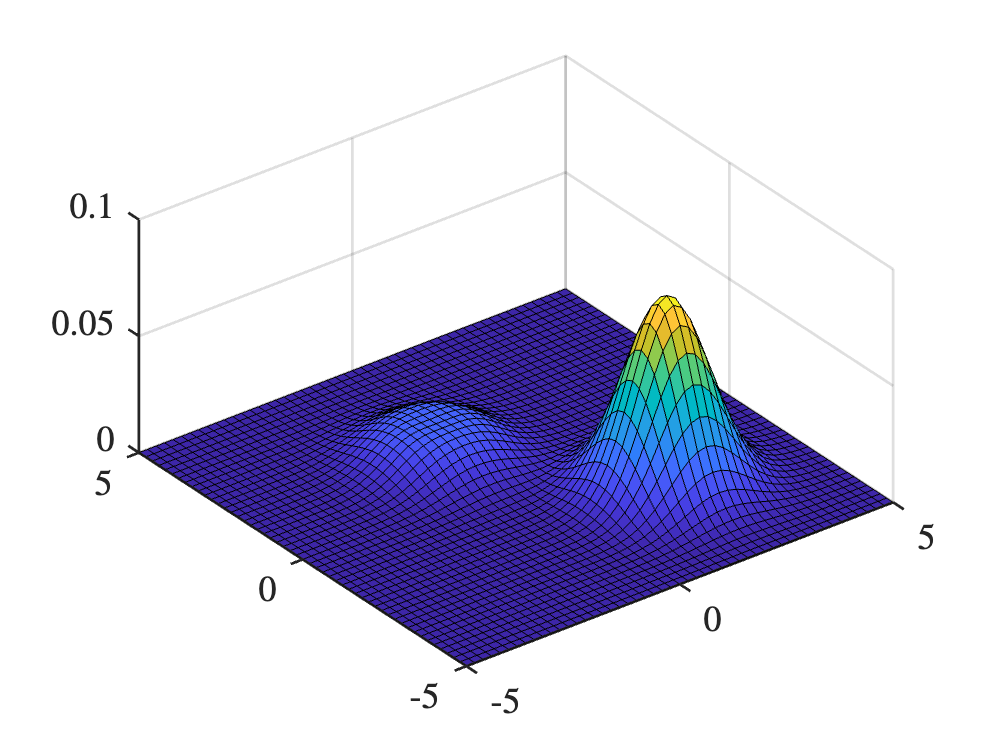

box.plot(rho_t(maskS),{});
xlabel(''); ylabel(''); zlabel('');

This is helpful since we want to solve the adjoint using an adaptive step method. 

With this, we have all the ingredients to evaluate the adjoint:

Q_t = Adjoint(u,v, Rho_t, dims, aLine, Conv, Diff);
%plots_in_box(Q_t, N_T, maskS,maskI,maskR, box,outTimes,Int_Spatial,'Adjoint-(u,v)-test.gif')

The adjoint is used to compute the derivative of the reduced objective functional:

% Retrieve involved components from state
S    = State_t(:,maskS);       I = State_t(:,maskI);       R = State_t(:,maskR);
% Retrieve each component of the adjoint
q_S  = Q_t(:,maskS);         q_I = Q_t(:,maskI);         q_R = Q_t(:,maskR);

% Precompute vectorial terms
RHS_aux = [S,S]' .* (grad * (G_S * q_S)') + [R,R]' .* (grad * (G_R * q_R)');
RHSdu = RHS_aux .*  (gConv_u * (S + R)');
RHSdv = RHS_aux .*  (gConv_v * I')  +  ...
            ( [I,I]' .* (grad * (G_I * q_I)') )  .*  (gConv_v * (S + I + R)');

% Partial derivatives
du = tik * u + (Int_Spatial * (RHSdu(1:N,:) + RHSdu(N+1:2*N,:)))';
dv = tik * v + (Int_Spatial * (RHSdv(1:N,:) + RHSdv(N+1:2*N,:)))';

% Assemble gradient
display(['Norm of scaled derivatives:  ', ...
    num2str([0.5 * (Int_Time * (du.^2))^0.5, 0.5 * (Int_Time * (dv.^2))^0.5]/(N_T))])

Norm of scaled derivatives:  2.1022       4.903


Let us also compute the objective value:

f = 0.5 * Int_Time * ((Int_Spatial * (I.^2)' )' + tik * (u.^2 + v.^2));
display(['Scaled objective:  ', num2str(f/(N_T^2))])

Scaled objective:  0.061956


We save the current state before running the algorithm itself:

State_Init = State_t;
u_Init = u;
v_Init = v;

## A projected gradient-descent algorithm

Now we aim to solve the OC problem using an optimisation scheme. For this we designed additional scripts to evaluate only the state and adjoint separately.

The function `State` computes the state variable for a given pair of parameters u and v. Since the initial condition does not change accross iterations, we provide it as an argument to reduce precomputations. Similarly, we provide the objects `dims`, and `aLine` so that the dimensions of the solution coincide with the state and are defined over the same domain of interest.

`    State(u,v, rho_ic, dims, aLine, Conv, Diff)`

Once a state has been computed, we can compute its corresponding adjoint using the function Adjoint.

`    Adjoint(u,v, State_t, dims, aLine, Conv, Diff)`

We proceed similarly with the `Objective` and `Gradient` functions:

`    Objective(u, v, State_t, tik, N, Int_Spatial, Int_Time)`

`    Gradient(u,v, State_t, Adjoint_t, N, Int_Spatial, gConv_u, gConv_v, grad, G, tik)`

Finally, we will also need a projection operator into the box [-B,B]^2:

fact    = 10.0;
Box_Lim = fact * D;

% Determine bounds and define projection
lb   = -Box_Lim;
ub   = min(Box_Lim, 0.5*D);
Proj = @(x) min( max(x,lb), ub);

Now we can write a code for the algorithm:

Nb_Its = 100;       % Number of iterations
critical = 1;      % Report status after this number of iterations

% Define majorant function
quad  =@(x,y, h_y, dh_y, L) h_y + sum((x-y) .* dh_y,'all') + 0.5 * L * sumsqr(x-y);
quadS =@(x,y, h_y, dh_y, L) h_y + sum(Int_Time * ((x-y) .* dh_y)) + ...
                            0.5 * L * Time_norm(x-y, 2, Int_Time)^2;

% Define objects to store information across iterates
crit    = zeros(Nb_Its + 1, 1);
State_t = State_Init;
alpha   = [u_Init, v_Init];
%State_t = State_p;
%alpha   = p;

f       = Objective(u_Init, v_Init, State_t, tik, N, Int_Spatial, Int_Time);
f       = f/(N_T^2); % We scale the system
crit(1) = f;
time    = zeros(Nb_Its,1);      % Time per iteration
dnIn    = zeros(Nb_Its, 1);     % Relative norm of inactive gradient
rnCo    = zeros(Nb_Its, 1);     % Relative sq-norm of control
rdCo    = zeros(Nb_Its, 1);     % Relative norm of difference between controls
cdiff   = zeros(Nb_Its, 1);     % Absolute value two consecutive objective iterations
U_Store = zeros(n_t,Nb_Its+1);  % Iterations in u
V_Store = zeros(n_t,Nb_Its+1);  % Iterations in v
U_Store(:,1) = alpha(:,1);
V_Store(:,1) = alpha(:,2);

% Stopping criteria
Stop_norm = 1e-10;
Stop_crit = 1e-10;

fprintf('   k |   f(αₖ)  | ᶦ‖df(ωₖ)‖ᵣ|   Time   |   ‖αₖ‖ᵣ² | ‖αₖ-αₖ₋₁‖ᵣ| |fₖ-fₖ₋₁|  \n')

   k |   f(αₖ)  | ᶦ‖df(ωₖ)‖ᵣ|   Time   |   ‖αₖ‖ᵣ² | ‖αₖ-αₖ₋₁‖ᵣ| |fₖ-fₖ₋₁|  


disp(strcat( repmat('–',1,75) ))

–––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––



% Initialisation
omega = alpha;
theta = 1;      % Inertia parameter
eta = 1.1;      % Scaling for backtracking                    % was 10
L = 1.1^6;      % Approximation of the Lipschitz constant     % was 10
I = 50;         % Number of iterations for backtracking

tols = 1e-7;
timing = 0.0;
L_tol = 2e-3;
reduce_L = true;    % Activate reduction of estimate for Lipschitz constant
reducedL = false;   % Check if constant has been reduced already
% Iterations
for it = 1:Nb_Its
    % Start measuring time
    start = tic;
    
    alpha_old = alpha;
    t_old = theta;
    f_old = f;
    
    %---------------------------------------------------------------
    % Function evaluation and adjoint for omega
    State_o   = State(omega(:,1),omega(:,2), rho_ic, dims, aLine, Conv, Diff, tols);
    State_o   = max(State_o, 0.0); % non-negativity
    Adjoint_o = Adjoint(omega(:,1),omega(:,2), State_o, dims, aLine, Conv, Diff, tols);
        
    h_y  = Objective(omega(:,1),omega(:,2), State_o, tik, N, Int_Spatial, Int_Time)/(N_T^2);
    dh_y = Gradient(omega(:,1),omega(:,2), State_o, Adjoint_o, N, Int_Spatial, ...
        gConv_u, gConv_v, grad, G, tik)/(N_T^2);
    
    if norm(dh_y,'inf') > (Box_Lim * 1.1)
        scale = (Box_Lim * 1.1)/norm(dh_y);
        %scale = 1/norm(dh_y);
    else
        scale = 1.0;
    end
    
    if (it > 2) && reduce_L
        if cdiff(it) < L_tol    %abs(f_old - crit(it-1)) < L_tol
            L = max(min(0.1, L/10), 1e-3);
            L_tol = L_tol * 1e-1
        end
        reducedL = true;

%         if abs(f_old - crit(it-1)) < 1e-5
%             L = 0.01;
%         end
%         if abs(f_old - crit(it-1)) < 1e-3 * crit(it-1)
%             L = L;
%         end
    end

    %---------------------------------------------------------------
    % backtracking
    for i = 0:I
        % temporary approximation of Lipschitz constant
        L_tmp = eta^i * L;
        b = 1/L_tmp;
        % Gradient and proximal step
        q = omega - b * scale * dh_y;       % did i made a mess somewhere?
        %fprintf('u = (%.6f,%.6f) \n',u)
        p = Proj(q);
        % Compute state to test validation of L_tmp
        State_p = State(p(:,1),p(:,2), rho_ic, dims, aLine, Conv, Diff, tols);
        State_p = max(State_p, 0.0); % non-negativity
        h_p     = Objective(p(:,1),p(:,2), State_p, tik, N, ...
                                Int_Spatial, Int_Time)/(N_T^2);
        %fprintf('(h_y, h_p) = (%.6f,%.6f) \n',[h_y, h_p])
        %fprintf('(h, q) = (%.6f,%.6f) \n',[h_p,quadS(p,omega, h_y,dh_y, L_tmp/scale)])
        %fprintf('%.0f \n',[h_p<quadS(p,omega, h_y,dh_y, L_tmp/scale)])
        
        %if h_p <= quad(p,omega, h_y,dh_y, L_tmp) + (1e-2)
        if h_p <= quadS(p,omega, h_y,dh_y, L_tmp/scale) %+ (1e-2)
            break
        elseif reducedL
            reduce_L = false; % Prevent reduction to take place
        end
        fprintf('%d ',i)
        %fprintf('%d %f %f\n',i,h_p, quad(p,omega, h_y,dh_y, L_tmp))
    end
    %---------------------------------------------------------------
    % Update control
    L     = L_tmp;
    alpha = p;
    % inertia update
    theta = (it + 2.2)/(2.2);
    omega = alpha + ((t_old - 1)/theta) * (alpha - alpha_old);
    
    % Measure time up to this point!
    timed = toc(start);
    timing = timing + timed;
    % Compute derivative information
    PG = Box_Decomposition(dh_y, p, lb,ub); % Decompose gradient
    
    % Store information
    % --------------------------------------------------------------
    time(it+1)  = timing;
    crit(it+1)  = h_p;
    dnIn(it+1)  = Time_norm(PG(:,:,3), inf, Int_Time)/sqrt(nnz(PG(:,:,3)) );
    rnCo(it+1)  = Time_norm(alpha, 2, Int_Time)^2 / n_t;
    rdCo(it+1)  = Time_norm(alpha-alpha_old, 2, Int_Time) / sqrt(n_t);
    cdiff(it+1) = abs(h_p-f_old);
    U_Store(:,it+1) = alpha(:,1);
    V_Store(:,it+1) = alpha(:,2);
    
    % Display if needed
    if(mod(it,critical)==0)
        Progress = sprintf('%4.0f | %.3e | %.3e | %8.2f | %.3e | %.3e | %.3e', ...
            [it, h_p, dnIn(it+1), timing, rnCo(it+1), rdCo(it+1), cdiff(it+1)]);
        display(regexprep( Progress, '(?<=e[-+])0', '' ))
    end
    % --------------------------------------------------------------
    
    if min(State_p,[],'all') < 0.0
        fprintf('Negative! %3.3f %', 100*numel(State_p(State_p < 0.0))/numel(State_p))
    end
    
    if rdCo(it+1) < Stop_norm
        fprintf('‖αₖ - αₖ₋₁‖ᵣ < %.e\n', Stop_norm)
        
        time  = time(1:it+1);   crit  = crit(1:it+1);   dnIn  = dnIn(2:it+1);
        rnCo  = rnCo(2:it+1);   rdCo  = rdCo(2:it+1);   cdiff = cdiff(2:it+1);
        U_Store = U_Store(:,1:it+1);
        V_Store = V_Store(:,1:it+1);
        break
    end
    
    if cdiff(it+1) < Stop_crit
        fprintf('|f(αₖ) - f(αₖ₋₁)| < %.e\n', Stop_crit)
        
        time  = time(1:it+1);   crit  = crit(1:it+1);   dnIn  = dnIn(2:it+1);
        rnCo  = rnCo(2:it+1);   rdCo  = rdCo(2:it+1);   cdiff = cdiff(2:it+1);
        U_Store = U_Store(:,1:it+1);
        V_Store = V_Store(:,1:it+1);
        break
    end
    
    f = h_p;
    
end

   1 | 5.463e-2 | 1.917e-2 |     2.34 | 1.320e-5 | 3.634e-3 | 7.326e-3
   2 | 4.971e-2 | 1.282e-2 |     4.68 | 5.218e-5 | 3.599e-3 | 4.924e-3
   3 | 4.527e-2 | 9.221e-3 |     7.06 | 1.349e-4 | 4.400e-3 | 4.436e-3
   4 | 3.987e-2 | 5.093e-3 |     9.85 | 3.745e-4 | 7.798e-3 | 5.397e-3
   5 | 3.754e-2 | 2.088e-3 |    13.46 | 5.952e-4 | 5.900e-3 | 2.333e-3
   6 | 3.626e-2 | 1.260e-3 |    16.59 | 8.021e-4 | 4.843e-3 | 1.284e-3


L_tol = 2.0000e-04

   7 | 3.359e-2 | 5.076e-4 |    20.25 | 2.236e-3 | 2.285e-2 | 2.669e-3
   8 | 3.318e-2 | 1.347e-4 |    24.13 | 3.398e-3 | 1.398e-2 | 4.110e-4
   9 | 3.304e-2 | 1.035e-4 |    27.39 | 4.122e-3 | 8.868e-3 | 1.371e-4


L_tol = 2.0000e-05

  10 | 3.291e-2 | 4.581e-5 |    30.82 | 5.123e-3 | 1.399e-2 | 1.337e-4
  11 | 3.285e-2 | 1.818e-5 |    34.60 | 5.911e-3 | 1.172e-2 | 5.395e-5
  12 | 3.282e-2 | 1.427e-5 |    38.26 | 6.568e-3 | 9.994e-3 | 2.903e-5
  13 | 3.280e-2 | 9.183e-6 |    41.52 | 7.146e-3 | 8.915e-3 | 1.965e-5


L_tol = 2.0000e-06

  14 | 3.276e-2 | 6.947e-6 |    45.02 | 8.656e-3 | 2.499e-2 | 4.259e-5
  15 | 3.274e-2 | 2.944e-6 |    48.69 | 1.005e-2 | 1.941e-2 | 1.955e-5
  16 | 3.274e-2 | 5.257e-6 |    53.07 | 1.084e-2 | 1.211e-2 | 4.635e-6
  17 | 3.273e-2 | 1.644e-6 |    56.87 | 1.132e-2 | 8.854e-3 | 2.217e-6
  18 | 3.273e-2 | 1.059e-6 |    61.40 | 1.165e-2 | 6.541e-3 | 9.089e-7


L_tol = 2.0000e-07

  19 | 3.273e-2 | 9.818e-7 |    65.67 | 1.189e-2 | 5.342e-3 | 5.358e-7
  20 | 3.273e-2 | 7.118e-7 |    69.76 | 1.205e-2 | 4.471e-3 | 3.312e-7
  21 | 3.273e-2 | 5.811e-7 |    73.78 | 1.218e-2 | 3.739e-3 | 2.121e-7
  22 | 3.273e-2 | 4.611e-7 |    77.84 | 1.229e-2 | 3.156e-3 | 1.377e-7


L_tol = 2.0000e-08

  23 | 3.273e-2 | 4.720e-7 |    82.13 | 1.240e-2 | 2.924e-3 | 1.012e-7
  24 | 3.273e-2 | 3.665e-7 |    86.35 | 1.247e-2 | 2.323e-3 | 6.358e-8
  25 | 3.273e-2 | 3.725e-7 |    90.97 | 1.255e-2 | 2.202e-3 | 5.628e-8
  26 | 3.273e-2 | 2.893e-7 |    96.98 | 1.261e-2 | 1.811e-3 | 3.566e-8
  27 | 3.273e-2 | 2.904e-7 |   101.62 | 1.267e-2 | 1.697e-3 | 3.192e-8
  28 | 3.273e-2 | 2.348e-7 |   106.40 | 1.272e-2 | 1.530e-3 | 2.660e-8
  29 | 3.273e-2 | 2.237e-7 |   110.95 | 1.276e-2 | 1.422e-3 | 2.057e-8
  30 | 3.273e-2 | 2.237e-7 |   115.13 | 1.280e-2 | 1.323e-3 | 1.651e-8


L_tol = 2.0000e-09

  31 | 3.273e-2 | 1.868e-7 |   119.39 | 1.285e-2 | 1.326e-3 | 1.621e-8
  32 | 3.273e-2 | 1.864e-7 |   123.74 | 1.288e-2 | 1.151e-3 | 1.054e-8
  33 | 3.273e-2 | 1.691e-7 |   128.19 | 1.291e-2 | 1.045e-3 | 6.945e-9
  34 | 3.273e-2 | 1.729e-7 |   132.67 | 1.294e-2 | 1.065e-3 | 6.604e-9
  35 | 3.273e-2 | 1.726e-7 |   137.12 | 1.297e-2 | 1.073e-3 | 8.735e-9
  36 | 3.273e-2 | 1.625e-7 |   141.75 | 1.299e-2 | 8.443e-4 | 5.300e-9
  37 | 3.273e-2 | 2.000e-7 |   146.10 | 1.301e-2 | 7.452e-4 | 4.145e-9
  38 | 3.273e-2 | 1.911e-7 |   150.37 | 1.303e-2 | 7.378e-4 | 3.755e-9
  39 | 3.273e-2 | 1.511e-7 |   154.51 | 1.305e-2 | 7.623e-4 | 4.356e-9
  40 | 3.273e-2 | 1.284e-7 |   158.66 | 1.307e-2 | 7.865e-4 | 4.465e-9
  41 | 3.273e-2 | 1.113e-7 |   162.87 | 1.309e-2 | 6.798e-4 | 3.531e-9
  42 | 3.273e-2 | 1.113e-7 |   167.22 | 1.310e-2 | 6.232e-4 | 2.339e-9
  43 | 3.273e-2 | 9.412e-8 |   171.42 | 1.311e-2 | 5.412e-4 | 1.989e-9


L_tol = 2.0000e-10

  44 | 3.273e-2 | 9.408e-8 |   175.47 | 1.312e-2 | 5.405e-4 | 1.928e-9
  45 | 3.273e-2 | 9.400e-8 |   179.64 | 1.313e-2 | 5.512e-4 | 2.058e-9
  46 | 3.273e-2 | 9.391e-8 |   183.57 | 1.315e-2 | 5.640e-4 | 2.164e-9
  47 | 3.273e-2 | 9.380e-8 |   187.65 | 1.316e-2 | 5.771e-4 | 2.196e-9
  48 | 3.273e-2 | 7.993e-8 |   191.85 | 1.317e-2 | 5.458e-4 | 2.101e-9
  49 | 3.273e-2 | 7.982e-8 |   195.96 | 1.318e-2 | 4.352e-4 | 1.304e-9
  50 | 3.273e-2 | 7.967e-8 |   199.99 | 1.319e-2 | 4.425e-4 | 1.263e-9
  51 | 3.273e-2 | 6.668e-8 |   203.94 | 1.320e-2 | 4.116e-4 | 1.033e-9
  52 | 3.273e-2 | 6.662e-8 |   208.12 | 1.321e-2 | 3.831e-4 | 6.647e-10
  53 | 3.273e-2 | 6.655e-8 |   212.21 | 1.322e-2 | 3.904e-4 | 7.073e-10
  54 | 3.273e-2 | 6.649e-8 |   216.20 | 1.322e-2 | 3.977e-4 | 7.596e-10
  55 | 3.273e-2 | 6.643e-8 |   220.36 | 1.323e-2 | 4.050e-4 | 6.155e-10
  56 | 3.273e-2 | 6.637e-8 |   224.56 | 1.324e-2 | 4.120e-4 | 7.330e-10
  57 | 3.273e-2 | 6.631e-8 |   228.85 | 1.325e-2 | 4.188e-4 | 7.435e-10


0 1 2 3 4 5 6 7 

  66 | 3.273e-2 | 4.548e-8 |   278.39 | 1.330e-2 | 2.669e-4 | 3.872e-10
  67 | 3.273e-2 | 4.542e-8 |   283.05 | 1.330e-2 | 2.622e-4 | 3.899e-10
  68 | 3.273e-2 | 4.536e-8 |   287.56 | 1.331e-2 | 2.579e-4 | 3.748e-10
  69 | 3.273e-2 | 4.531e-8 |   292.33 | 1.331e-2 | 2.540e-4 | 3.504e-10
  70 | 3.273e-2 | 4.525e-8 |   296.85 | 1.332e-2 | 2.505e-4 | 3.627e-10
  71 | 3.273e-2 | 4.520e-8 |   300.84 | 1.332e-2 | 2.472e-4 | 3.597e-10
  72 | 3.273e-2 | 4.514e-8 |   305.17 | 1.333e-2 | 2.442e-4 | 3.715e-10
  73 | 3.273e-2 | 3.137e-8 |   309.30 | 1.333e-2 | 1.512e-4 | 1.792e-10
  74 | 3.273e-2 | 3.133e-8 |   313.33 | 1.333e-2 | 1.491e-4 | 1.558e-10
  75 | 3.273e-2 | 3.129e-8 |   317.71 | 1.333e-2 | 1.477e-4 | 1.712e-10
  76 | 3.273e-2 | 3.126e-8 |   322.73 | 1.334e-2 | 1.465e-4 | 1.763e-10
  77 | 3.273e-2 | 3.122e-8 |   327.34 | 1.334e-2 | 1.453e-4 | 1.610e-10
  78 | 3.273e-2 | 3.118e-8 |   331.59 | 1.334e-2 | 1.443e-4 | 1.711e-10
  79 | 3.273e-2 | 3.115e-8 |   335.92 | 1.334e-2 | 1.434e-4 | 1.

0 1 2 3 4 5 6 7 8 9 10 11 12 

  83 | 3.273e-2 | 3.100e-8 |   371.95 | 1.335e-2 | 1.373e-4 | 1.526e-10
  84 | 3.273e-2 | 3.097e-8 |   376.40 | 1.335e-2 | 1.335e-4 | 1.535e-10
  85 | 3.273e-2 | 3.094e-8 |   380.76 | 1.336e-2 | 1.300e-4 | 1.485e-10
  86 | 3.273e-2 | 3.091e-8 |   385.01 | 1.336e-2 | 1.266e-4 | 1.279e-10
  87 | 3.273e-2 | 3.087e-8 |   389.25 | 1.336e-2 | 1.234e-4 | 1.519e-10
  88 | 3.273e-2 | 3.084e-8 |   394.10 | 1.336e-2 | 1.204e-4 | 1.455e-10
  89 | 3.273e-2 | 3.081e-8 |   398.98 | 1.336e-2 | 1.175e-4 | 1.138e-10
  90 | 3.273e-2 | 3.079e-8 |   403.65 | 1.337e-2 | 1.147e-4 | 1.270e-10
  91 | 3.273e-2 | 3.076e-8 |   407.89 | 1.337e-2 | 1.122e-4 | 1.317e-10
  92 | 3.273e-2 | 3.073e-8 |   412.71 | 1.337e-2 | 1.097e-4 | 1.169e-10
  93 | 3.273e-2 | 3.070e-8 |   417.50 | 1.337e-2 | 1.073e-4 | 1.158e-10


0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 

  94 | 3.273e-2 | 2.951e-8 |   449.39 | 1.337e-2 | 1.035e-4 | 1.024e-10
  95 | 3.273e-2 | 2.948e-8 |   453.18 | 1.337e-2 | 8.771e-5 | 4.204e-11


|f(αₖ) - f(αₖ₋₁)| < 1e-10


disp(strcat( repmat('–',1,75) ))

–––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––––


fprintf('\nNorm of inactive gradient ᶦ‖df(αₖ)‖ ≈ ᶦ‖df(ωₖ)‖ = %.3e.\n\n', dnIn(it) )


Norm of inactive gradient ᶦ‖df(αₖ)‖ ≈ ᶦ‖df(ωₖ)‖ = 2.948e-08.



fprintf('\nAlgorithm stopped after %.4f seconds and %.0f iterations.\n\n', ...
    [time(it+1),it])


Algorithm stopped after 453.1850 seconds and 95 iterations.



Evaluate negativity:

fprintf('Negativity %3.2f%%', 100*numel(State_p(State_p < 0.0))/numel(State_p))

Negativity 0.00%

Evaluate derivative at current point:

Adjoint_p = Adjoint(p(:,1),p(:,2), State_p, dims, aLine, Conv, Diff, tols);
dh_p = Gradient(p(:,1),p(:,2), State_p, Adjoint_p, N, Int_Spatial, gConv_u, gConv_v, grad, G, tik)/(N_T^2);

Evaluate optimality:

PG = Box_Decomposition(dh_p, p,lb,ub); % Decompose gradient

%disp(min(State_p,[],'all'))
%[all(dh_y(p==lb) >= 0), all(dh_y(p==ub) <= 0)]
fprintf(['\nActive set optimality check:' ...
    '\n   (df(α)|α=lb ≥ 0) & (df(α)|α=ub ≤ 0): %s.\n\n'], ...
        mat2str([ all(PG(:,:,1)>= 0), all(PG(:,:,2)<= 0)]) )


Active set optimality check:
   (df(α)|α=lb ≥ 0) & (df(α)|α=ub ≤ 0): [true true true true].



%norm( dh_y((p > lb) & (p< ub)) / numel(dh_y((p > lb) & (p< ub))) )


%sqrt( sum( Int_Time'.*PG(:,:,3).^2, 'all','omitnan')/sum(~isnan(PG(:,:,3)),'all') )
fprintf(['\n Norm of inactive gradient:' ...
    '\n  ‖·‖∞ = %.3e, ‖·‖₂ = %.3e'], [Time_norm(PG(:,:,3), inf, Int_Time)/sqrt(nnz(PG(:,:,3)) ),
    Time_norm(PG(:,:,3), 2, Int_Time)/sqrt(nnz(PG(:,:,3)) )])


 Norm of inactive gradient:
  ‖·‖∞ = 2.948e-08, ‖·‖₂ = 2.268e-08


%Time_norm(PG(:,:,3), 2, Int_Time)/sqrt(nnz(PG(:,:,3)) )
%Time_norm(PG(:,:,3), 2, Int_Time)/sqrt(numel(PG(:,:,3)))
%max( abs(PG(:,:,3)), [], 'all')/sqrt(sum(~isnan(PG(:,:,3)),'all'))
%Time_norm(PG(:,:,3), inf, Int_Time)/sqrt(numel(PG(:,:,3)))